clc
clear

u = symunit;

syms x x_dot x_ddot y y_ddot y_ddot

x_koord = x
v_a = x_dot
a_a = x_ddot

y_koord = y
v_b = y_ddot
a_b = y_ddot


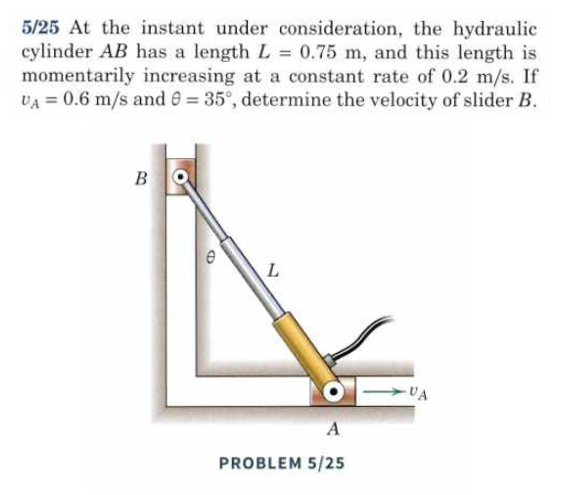

clc
clear
u = symunit;

L = 0.75*u.m; v_L = 0.2 * u.m/u.s; L_dot = v_L;

theta = 35;

x_dot = 0.6 * u.m/u.s; x = sind(theta) * L;

y = sqrt(L^2 - x^2);

y_dot = (L*L_dot - x*x_dot)/y;
v_B = vpa(y_dot, 3)


clc
clear

u = symunit;
syms b theta h d w

k = b*sin(theta) + h

x1 = cos(theta)*b + sqrt(d^2 - k^2)

xx1 = diff(x1, theta)*w
xx2 = diff(x2, theta)*w

x = xx1 + xx2
var = subs(x,[b,d,h,theta,w],[80*u.mm, 100*u.mm, 30*u.mm, deg2rad, -7/u.s])
var = vpa(var)


clc
clear

syms b theta h d w x

k = b*sin(theta) + h

$$k = h+b\,\sin\left(\theta \right)$$


x1 = cos(theta)*b + sqrt(d^2 - k^2)

$$x1 = b\,\cos\left(\theta \right)+\sqrt{d^{2}-{\left(h+b\,\sin\left(\theta \right)\right)}^{2}}$$



f = @(theta) cos(theta)*b + sqrt(d^2 - k^2)

f = function_handle with value:
    @(theta)cos(theta)*b+sqrt(d^2-k^2)


diff(f, theta)

$$ans = -b\,\sin\left(\theta \right)-\frac{b\,\cos\left(\theta \right)\,\left(h+b\,\sin\left(\theta \right)\right)}{\sqrt{d^{2}-{\left(h+b\,\sin\left(\theta \right)\right)}^{2}}}$$


functionalDerivative(f, theta(x))

Error using sym/subsindex
Invalid
indexing
or
function
definition.
Indexing
must
follow
MATLAB
indexing.
Function
arguments
must
be
symbolic
variables,
and
function
body
must
be sym
expression.

Error in indexing (line 1075)
            R_tilde = builtin('subsref',L_tilde,Idx);

Related documentation